# Radar Signal Processing Verification

This script has been written to confirm that the signal processing component of a radar is working as anticipated

## Initialize the simulator

clear;
simulator = Simulator_revB();
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
% file_path = "B210_params.json";
% file_path = "B210_params_highBW.json";
% file_path = "B210_params_highvres.json";
% file_path = "B210_params_lowBW.json";
% file_path = "B210_params_sensing_system.json";
% file_path = "X310_params_100MHzBW.json";
% file_path = "realistic_params.json";
file_path = "realistic_long_range.json";
simulator.load_params_from_JSON(david_path + file_path);

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 83.33 MHz/us
	 Idle Time: 			 1.16 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 85.33 MSps
	 Ramp End Time: 		 18.32 us
	 Chirp Tx Bandwidth: 		 1526.37 MHz
	 Chirp Sampling Bandwidth: 	 1000.00 MHz
	 ADC Sampling Period: 		 12.00 us
	 Chirp Cycle Time: 		 19.48 us
	 Chirp Wavelength: 		 3.89 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 4.99 ms


%log detection first, then log all the data about it
simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 153.49 m
	 Range Resolution 		 0.15 m
	 Max Velocity 			 49.97 m/s
	 Velocity Resolution 		 0.39 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 1535.94 MHz
	 Downsampling factor 		 18
	 Sweep time 			 18.32 us
	 Samples per chirp 		 29916.00 


## Initialize the Target

simulator.load_target_realistic(50, -25);

## Run the simulation

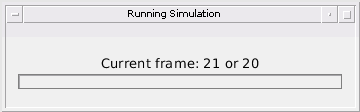

%specify the number of frames and chirps to compute
frames_to_compute = 20;

%specify whether or not to record a move of the range-doppler plot
record_movie = true;
simulator.Victim.Radar_Signal_Processor.configure_movie_capture(frames_to_compute,record_movie);

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

%run the simulation (without an attacker for now)
simulator.run_simulation_no_attack(frames_to_compute,true);

## Results

% determine if an object has been detected in each frame
detected = performance_functions.detection(frames_to_compute, simulator.Victim.Radar_Signal_Processor.range_estimates)

detected =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0   

% report the range estimates
estimated_ranges = simulator.Victim.Radar_Signal_Processor.range_estimates

estimated_ranges =    49.9302       NaN       NaN       NaN       NaN
   48.9905       NaN       NaN       NaN       NaN
   48.0921       NaN       NaN       NaN       NaN
   47.2123       NaN       NaN       NaN       NaN
   46.3287       NaN       NaN       NaN       NaN
   45.4105       NaN       NaN       NaN       NaN
   44.4850       NaN       NaN       NaN       NaN
   43.6028       NaN       NaN       NaN       NaN
   42.7225       NaN       NaN       NaN       NaN
   41.8261       NaN       NaN       NaN       NaN


% compute the actual range per frame
actual_ranges = performance_functions.actual_ranges(frames_to_compute, simulator.Victim.FramePeriodicity_ms*.001, simulator.SimulatedTarget.velocity_meters_per_s, simulator.Victim.velocity_m_per_s, simulator.SimulatedTarget.position_m, simulator.Victim.position_m)

actual_ranges =    50.0000   49.1162   48.2666   47.4530   46.6774   45.9416   45.2477   44.5974   43.9929   43.4360   42.9285   42.4722   42.0688   41.7199   41.4267   41.1905   41.0123   40.8929   40.8326   40.8319


% compute the percent error of the range estimate for each frame
percent_error_ranges = performance_functions.range_percent_error(actual_ranges, estimated_ranges)

percent_error_ranges =     0.0698
    0.1257
    0.1744
    0.2407
    0.3487
    0.5311
    0.7627
    0.9947
    1.2704
    1.6098


% report the velocity estimates
estimated_velocities = simulator.Victim.Radar_Signal_Processor.velocity_estimates

estimated_velocities =    26.8319       NaN       NaN       NaN       NaN
   26.7966       NaN       NaN       NaN       NaN
   26.8852       NaN       NaN       NaN       NaN
   26.9150       NaN       NaN       NaN       NaN
   26.8743       NaN       NaN       NaN       NaN
   26.7892       NaN       NaN       NaN       NaN
   26.8468       NaN       NaN       NaN       NaN
   26.9095       NaN       NaN       NaN       NaN
   26.9028       NaN       NaN       NaN       NaN
   26.8279       NaN       NaN       NaN       NaN


% compute the actual velocity per frame
actual_velocities = performance_functions.actual_velocities(frames_to_compute, simulator.SimulatedTarget.velocity_meters_per_s, simulator.Victim.velocity_m_per_s)

actual_velocities =     27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27


% compute the velocity percent error per frame
percent_error_velocities = performance_functions.velocity_percent_error(estimated_velocities, actual_velocities)

percent_error_velocities =    -0.1681
   -0.2034
   -0.1148
   -0.0850
   -0.1257
   -0.2108
   -0.1532
   -0.0905
   -0.0972
   -0.1721


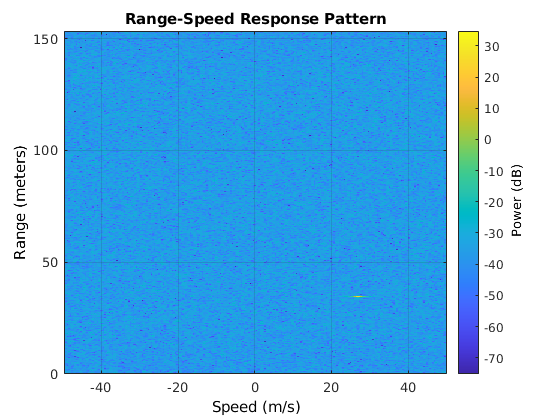

%play the movie for the range doppler
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_range_doppler_movie();
end

%play the movie for the clusters
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_clustering_movie()
end